# Working with Images in MATLAB

## Import, Display, and Write Images

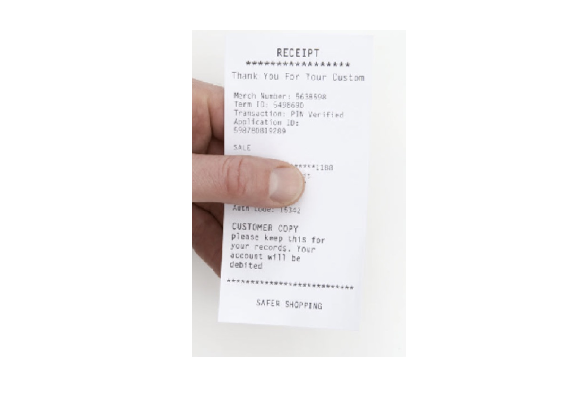

I = imread("img/IMG_001.jpg");
imshow(I)

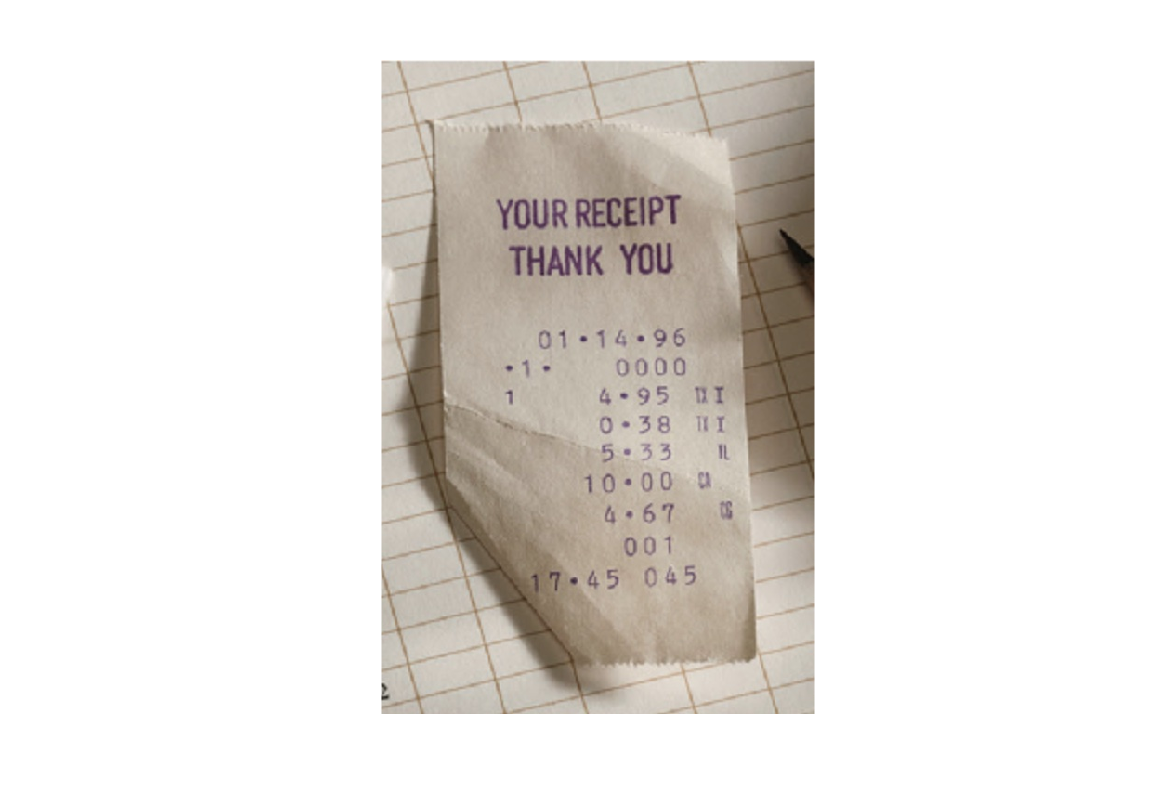


I2 = imread("img/IMG_002.jpg");
imshow(I2)

如果要讓兩張 image 並排顯示，可用以下語法 (可用 `help imshowpair` 看詳細資訊)

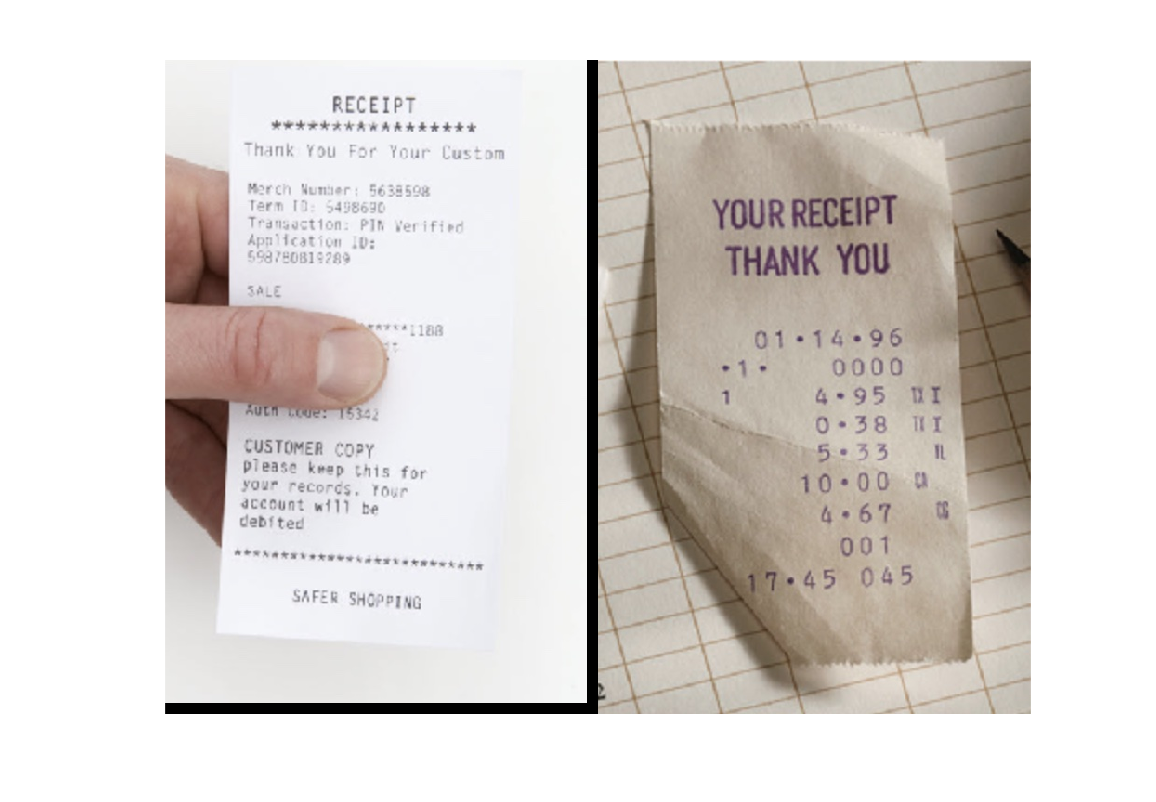

imshowpair(I,I2,"montage") % montage 是 side-by-side 的意思

要存檔的話，使用以下語法

% imwrite(I, "img.jpg") % 利用副檔名，來指定要存出來的格式

## Color Planes and Intensity Values

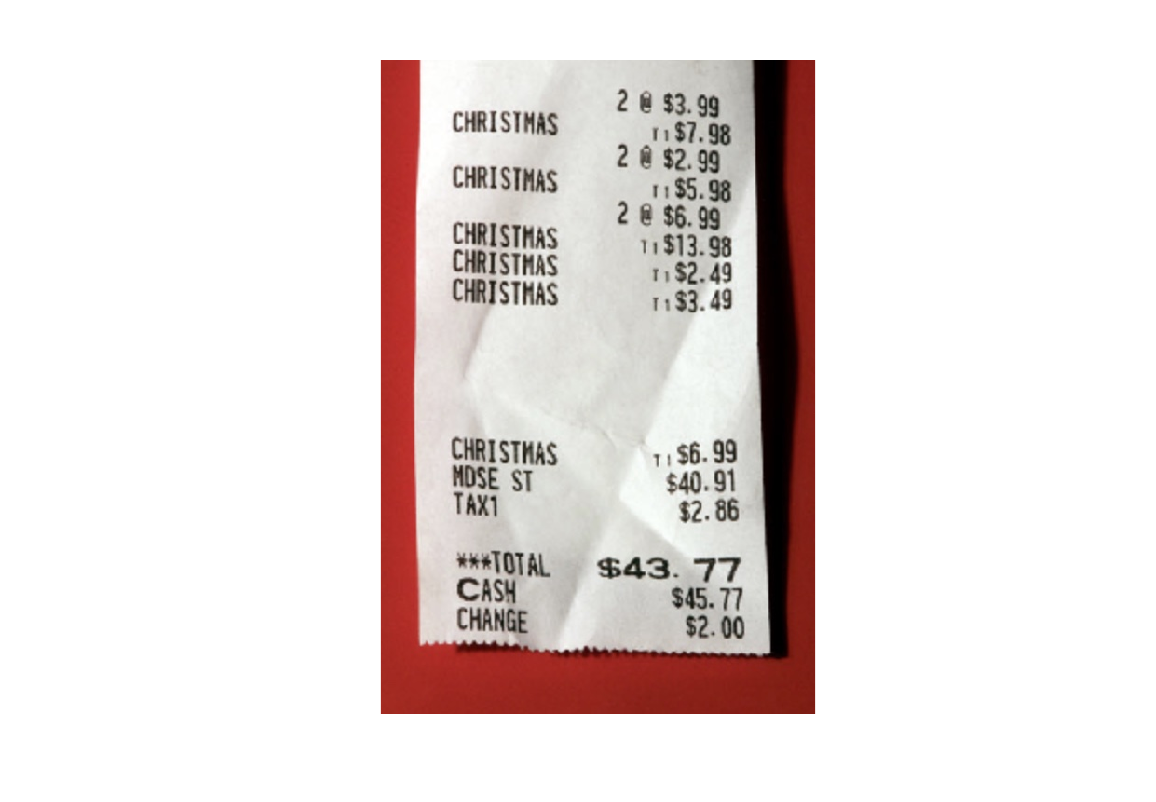

I = imread("img/IMG_003.jpg");
imshow(I)

看 shape，用的指令是 `size`

sz = size(I)

sz =    702   466     3


取三個通道的影像出來

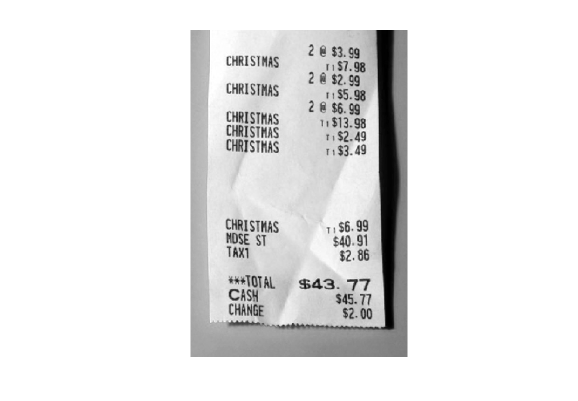

R = I(:,:,1);
G = I(:,:,2);
B = I(:,:,3);
imshow(R)

大部分的影像，都是存成 `uint8`，也就是 (unsigned 8-bit integer)，所以數值介於 0 ~ 255

我們來看看，紅色通道中，最大值是不是有到 255

Rmax = max(R, [], "all") % 中間的括號，是作為中間參數的 placeholder，必填; 

Rmax = uint8
255

                         % 最後的 "all"，是找所有 element 中的最大值的意思
Rmin = min(R, [], "all")

Rmin = uint8
0

現在來教你大招 (pro 會用的)

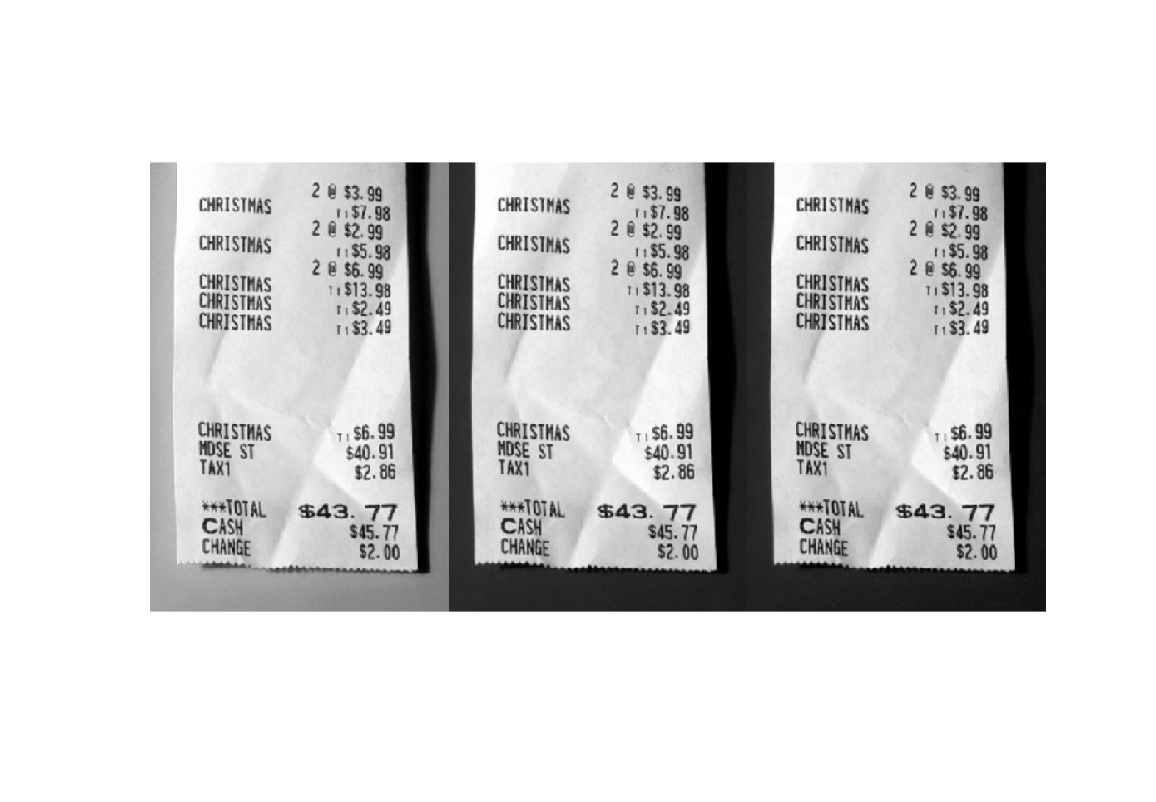

[R,G,B] = imsplit(I); % 一步就幫你切開三個通道
montage({R,G,B}) % 一次顯示三個通道的影像

## Convert to Grayscale

轉灰階可以讓容量變小，且在做 processing 的時候更單純

條件是，原始的資訊，轉灰階不會喪失太多重要資訊 (例如收據的例子，重點是白紙黑字的資訊，至於背景的顏色並不 care，那就蠻適合轉灰階的)

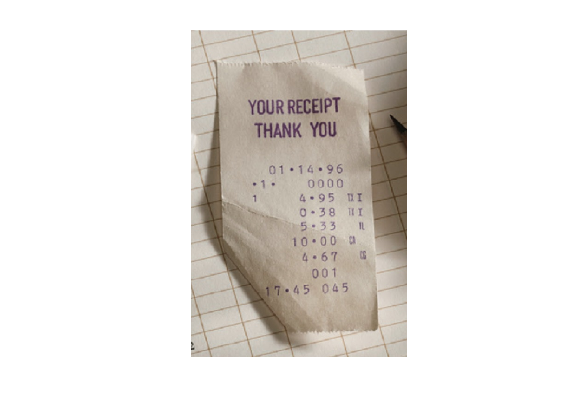

I = imread("img/IMG_002.jpg");
imshow(I)

轉灰階

gs = im2gray(I);
sz = size(gs)

sz =    704   466


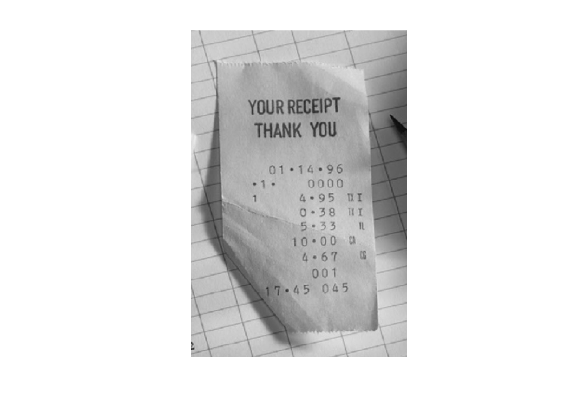

imshow(gs)

官網文件有提供轉換公式： `0.2989 * R + 0.5870 * G + 0.1140 * B`

`另外，如果將灰階影像存出去，那到時候讀影像時，讀到灰階，他就會是二維矩陣`

imwrite(gs, "img/gs_img002.jpg");
gs_load = imread("img/gs_img002.jpg");
size(gs_load)

ans =    704   466


## Adjusting Image Contrast

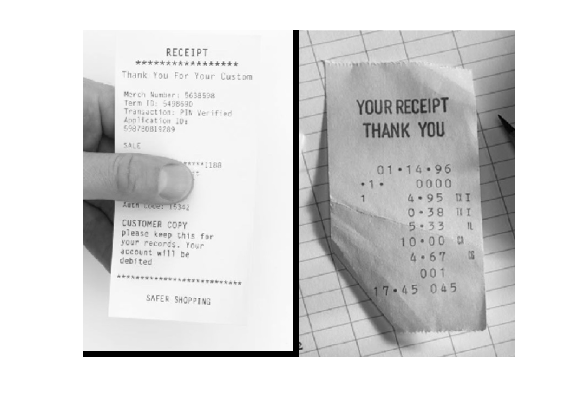

I = imread("img/IMG_001.jpg");
I2 = imread("img/IMG_002.jpg");
gs = im2gray(I);
gs2 = im2gray(I2);
imshowpair(gs,gs2,"montage")

可以用 histogram 來看顏色分佈

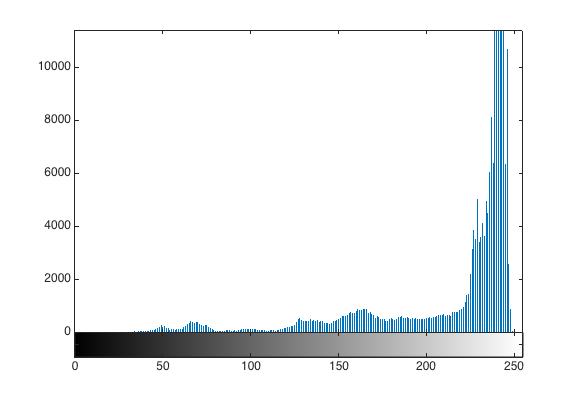

imhist(gs)

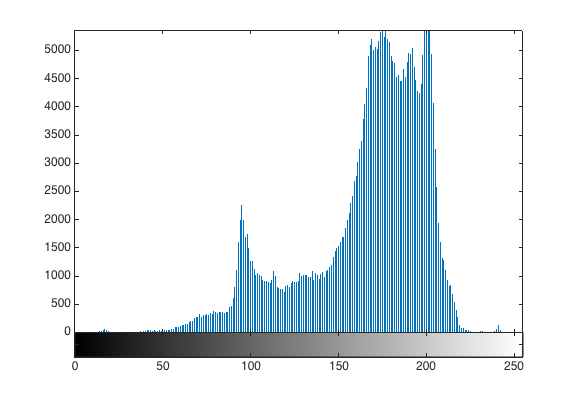

imhist(gs2)

從分佈的 range，可以發現 gs2 比較窄，gs比較寬，比較原圖也可發現，第一張影像的對比較高，第二張較低。

matlab 有個 function 可以幫你直接調對比度，他會 brighten brighter pixels and darkens darker pixels

來看看效果

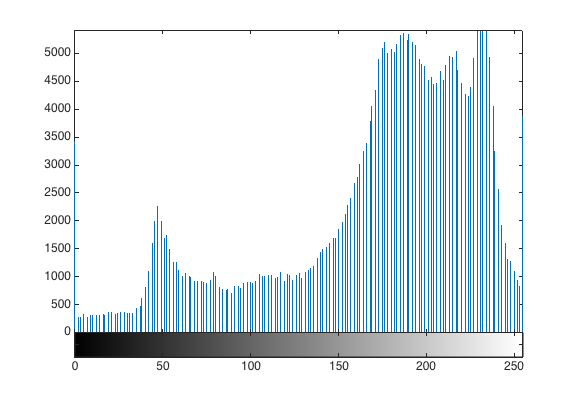

gs2Adj = imadjust(gs2);
imhist(gs2Adj)

可以看到 histogram 被拉開了，但不確定他是用什麼方法 (看起來有點像 histogram equalization，但說明文件沒明確寫轉換方式)

來看看效果吧：

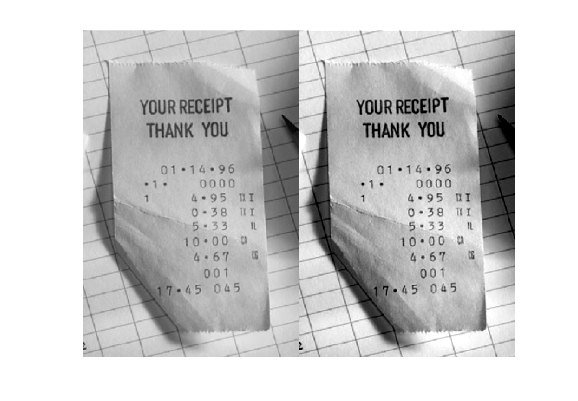

imshowpair(gs2, gs2Adj, "montage")

最後， `imadjust()` 只適用在灰階影像，如果要對彩色影像做加強對比，請用 `imlocalbrighten()`

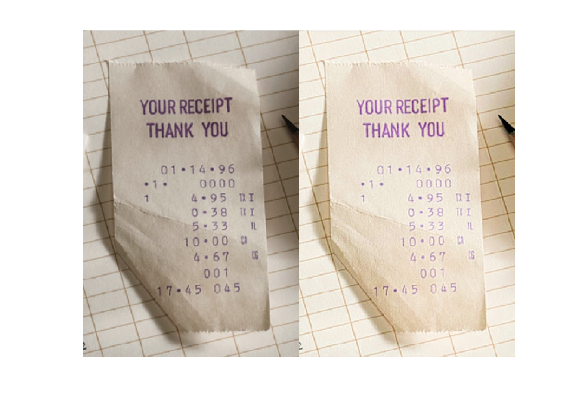

I2adj = imlocalbrighten(I2);
imshowpair(I2, I2adj, "montage")

## Image Viewer App

matlab 有一個 app，可以讓你用滑鼠點一點，就把剛剛的資訊都 show 給你看，也讓你快速的做些 processing

點最上面的 `APPS` 頁籤，再點 APPS 裡的下拉式選單，在 `IMAGE_PROCESSING & COMPUTER VISION` 裡面，可以找到 `Image Viewer`

`點開來就可以玩一玩了 (就像 imageJ 這樣)`